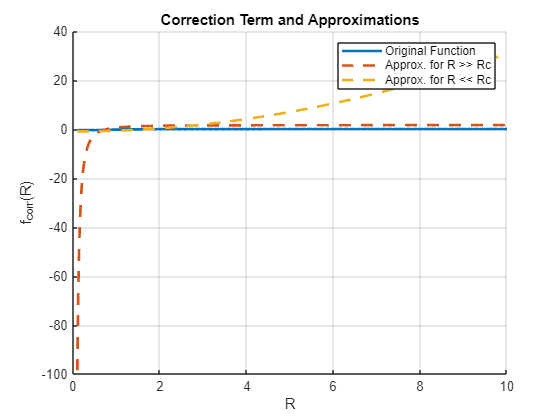

% Parameters
alpha = 1;            % Example value for alpha
Rc = 1;               % Example value for Rc (characteristic radius)
R = linspace(0.1, 10, 500); % Range of R values (avoid R = 0)

% Original function
f_corr = -(alpha/pi) * Rc .* atan(Rc^2 ./ R.^2);

% Approximation for R >> Rc
f_corr_approx_high = (pi/2) - (Rc^2 ./ R.^2);

% Approximation for R << Rc
f_corr_approx_low = -(alpha/pi) * Rc * (pi - (R.^2 ./ Rc^2));

% Plotting the functions
figure;
hold on;

% Plot original function
plot(R, f_corr, 'LineWidth', 2, 'DisplayName', 'Original Function');

% Plot approximations
plot(R, f_corr_approx_high, '--', 'LineWidth', 2, 'DisplayName', 'Approx. for R >> Rc');
plot(R, f_corr_approx_low, '--', 'LineWidth', 2, 'DisplayName', 'Approx. for R << Rc');

% Add labels and title
xlabel('R');
ylabel('f_{corr}(R)');
title('Correction Term and Approximations');
legend;
grid on;
hold off;